clear
clc
close all
format long

%%%%%%%%%%%%%%%%% READ TABLE %%%%%%%%%%%%%%%%%%%
t = readtable('star_classification.csv');

alpha = t{:,2};
delta = t{:,3};
u = t{:,4};
g = t{:,5};
r = t{:,6};
i = t{:,7};
z = t{:,8};
class = categorical(t{:,14});
redshift = t{:,15};

T = table(delta, u, g, r, z, redshift, class);

%%%%%%%%%%%%%%% FILTER OUTLIER %%%%%%%%%%%%%%%
filter = T.u > 0 & T.g > 0 & T.z > 0;
T = T(filter, :);
class = class(filter, :);

X = T{:,1:end-1};

X = normalize(X);

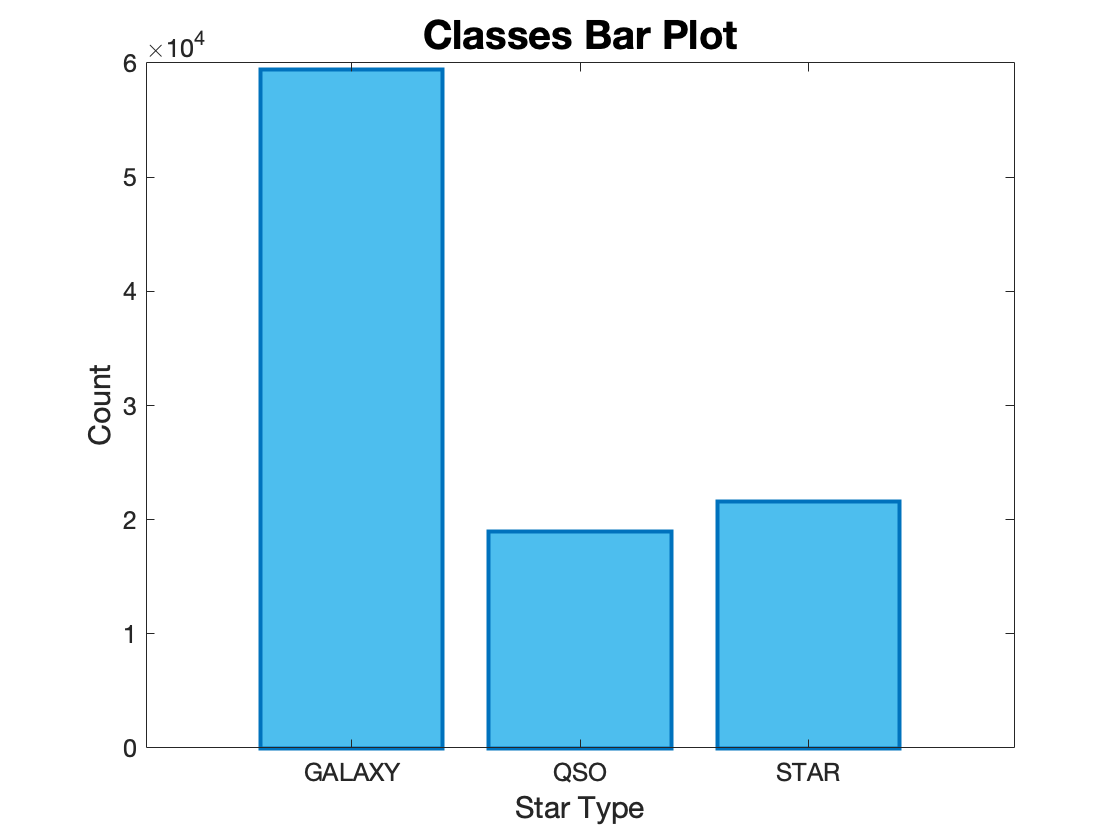

%%%%%%%%%%%%%%%% PLOT 1D VARIABLES %%%%%%%%%%%%%%%%%%%%%%%%

% use tabulate to count and obtain data needed and plot
tab1 = tabulate(class);
% transform into table
classes = cell2table(tab1,'VariableNames', ...
    {'Value','Count','Percent'});
% plot bar graph
bar(categorical(classes.Value), classes.Count, 'EdgeColor', '#0072BD', ...
                                  'LineWidth', 2,...
                                  'FaceColor', '#4DBEEE')
% add labels
set(gca, 'fontsize', 12.5)
xlabel('Star Type', 'fontsize', 15)
ylabel('Count', 'fontsize', 15)
title('Classes Bar Plot', 'fontsize', 20)

%

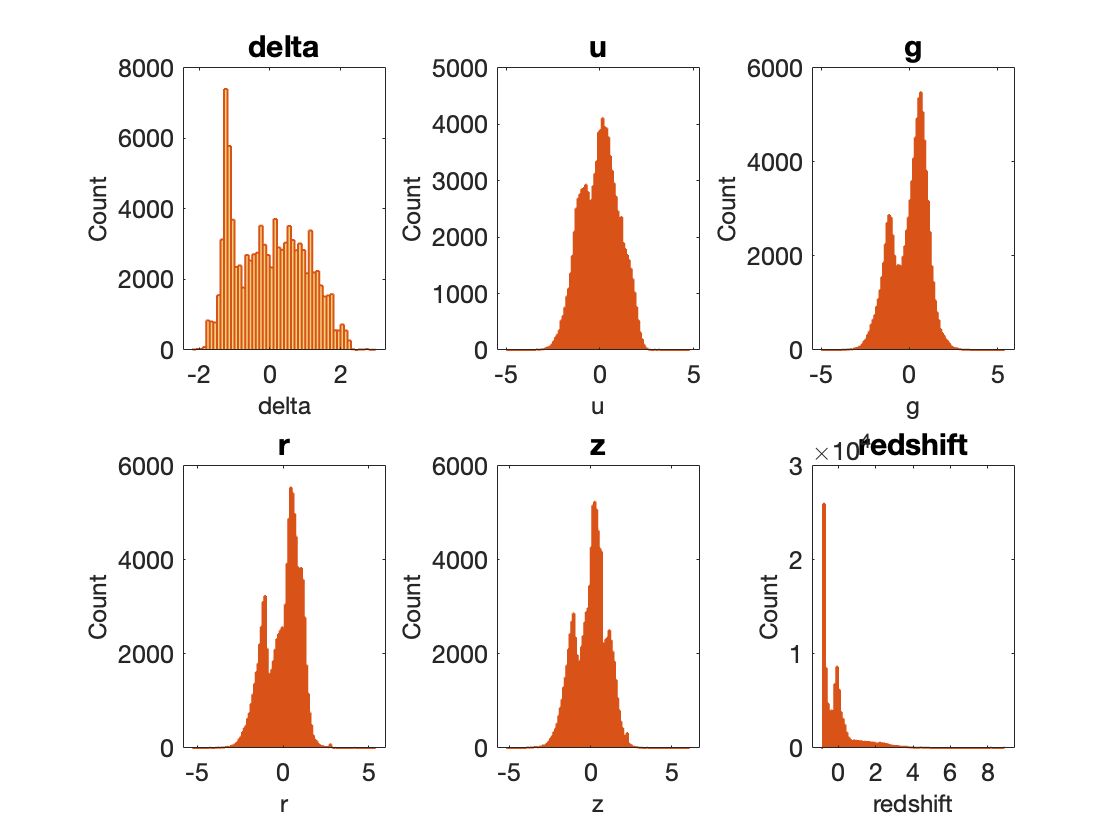

%%%%%%%%%%%% HISTOGRAM OF EACH VARIABLE %%%%%%%%%%%%%%%%%%%%
variables = ["delta", "u", "g", "r", "z", "redshift"];
figure;
for c = 1:numel(variables)
    subplot(2,3,c)
    histogram(X(:, c), 'EdgeColor', '#D95319', ...
    'LineWidth', 1,...
    'FaceColor', '#EDB120')

    set(gca, 'fontsize', 12.5)
    xlabel(variables(c), 'fontsize', 12)
    ylabel('Count', 'fontsize', 12)
    title(variables(c), 'fontsize', 15)
end

%

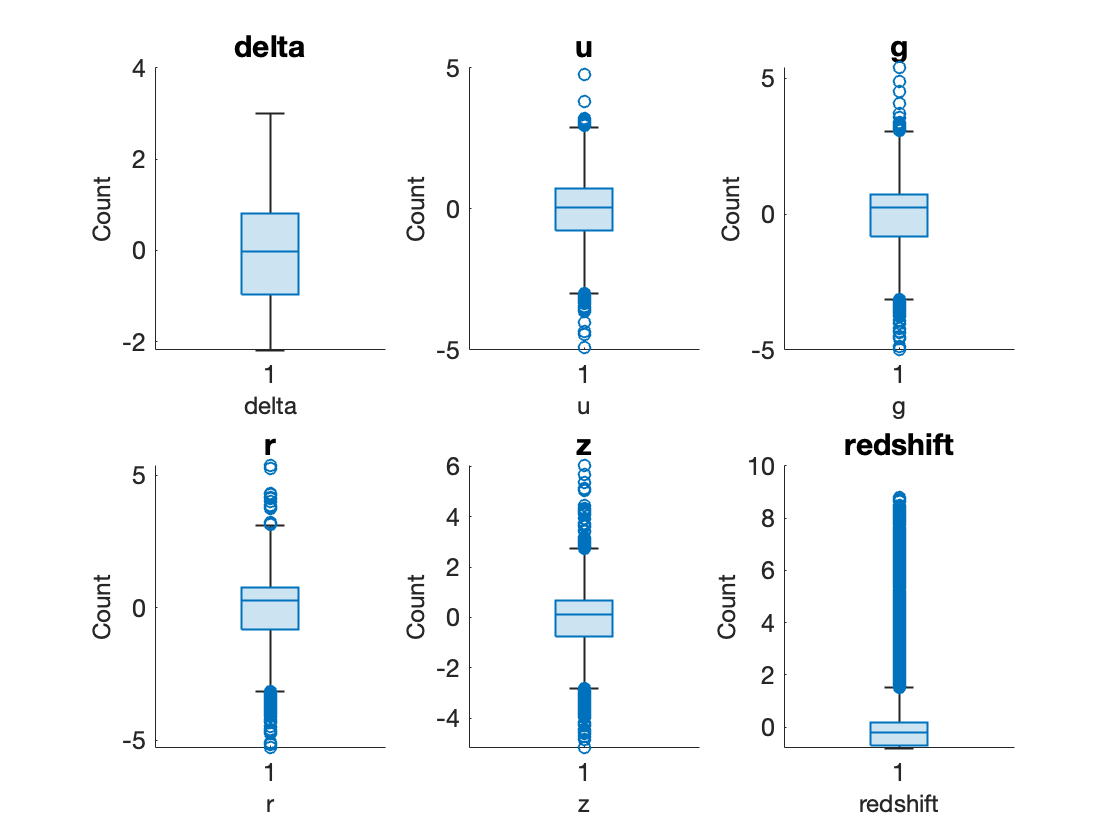

%%%%%%%%%%%% BOXPLOT OF EACH VARIABLE %%%%%%%%%%%%%%%%%%%%
figure;
for c = 1:numel(variables)
    subplot(2,3,c)
    boxchart(X(:, c))

    set(gca, 'fontsize', 12.5)
    xlabel(variables(c), 'fontsize', 12)
    ylabel('Count', 'fontsize', 12)
    title(variables(c), 'fontsize', 15)
end

%

%%%%%%%%%%%%%%%% MANUAL CLUSTERING %%%%%%%%%%%%%%%%%%%%%%
% find number of data points
n = size(class, 1);

% create empty class vector
class2 = zeros(n, 1);

% seperate data into 2 classes
for c = 1:n
    if class(c) == 'QSO'
        class2(c) = 1;
    end
    
end

group0 = X(class2 == 0, :);
group1 = X(class2 == 1, :);
grouped = [group0;group1];

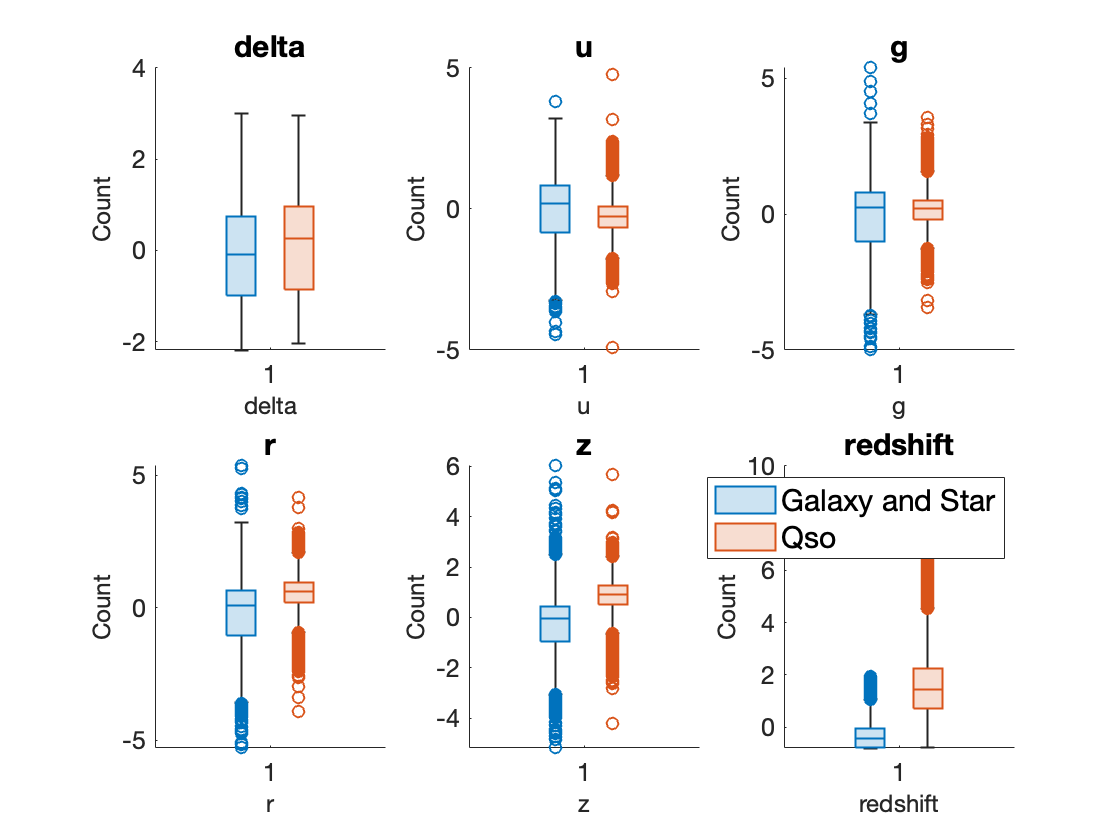

%%%%%%%%%%%% SIDE BY SIDE BOXPLOT %%%%%%%%%%%%%%%%%%%%
c1 = zeros(81038, 1);
c2 = ones(18961, 1);
groupedclass = [c1;c2];


figure;
for c = 1:numel(variables)
    subplot(2,3,c)
    boxchart(grouped(:, c),'GroupByColor', groupedclass)

    set(gca, 'fontsize', 12.5)
    xlabel(variables(c), 'fontsize', 12)
    ylabel('Count', 'fontsize', 12)
    title(variables(c), 'fontsize', 15)
end
% add legend and grid
speciesList = {'Galaxy and Star', 'Qso'};
legend(speciesList, 'fontsize', 15)

%

%%%%%%%%%%%%%%%% APPLY PCA %%%%%%%%%%%%%%%%%%%%%%%%%%
Y = pca(grouped);

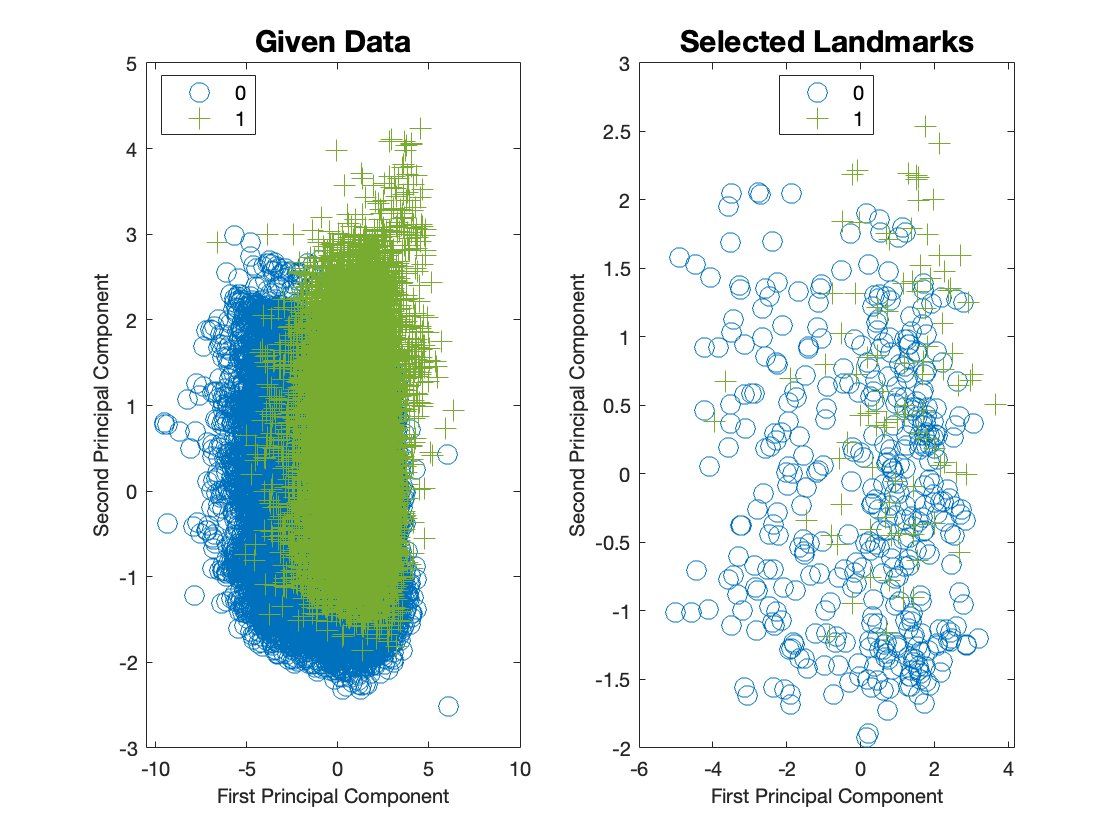

%%%%%%%%%%%%%%%%% SELECT LANDMARKS %%%%%%%%%%%%%%%%%
truelabels = groupedclass;
n = size(Y,1);      % number of data points
m = 500;            % number of landmark points
subset = sort(randsample(n,m));

figure; 
subplot(1,2,1)
gscatter(Y(:,1), Y(:,2), truelabels, ...
    [0, .447, .741; .466, .674, .188], ...
    'o+', 10)
set(gca,'fontsize',10)
xlabel('First Principal Component', 'fontsize', 10)
ylabel('Second Principal Component', 'fontsize', 10)
legend('fontsize',10)
title('Given Data', 'FontSize',15)

landmarks = Y(subset,:); 
subplot(1,2,2)
gscatter(landmarks(:,1), landmarks(:,2), truelabels(subset), ...
    [0, .447, .741; .466, .674, .188], ...
    'o+', 10)
set(gca,'fontsize',10)
xlabel('First Principal Component', 'fontsize', 10)
ylabel('Second Principal Component', 'fontsize', 10)
legend('fontsize',10)
title('Selected Landmarks', 'FontSize',15)

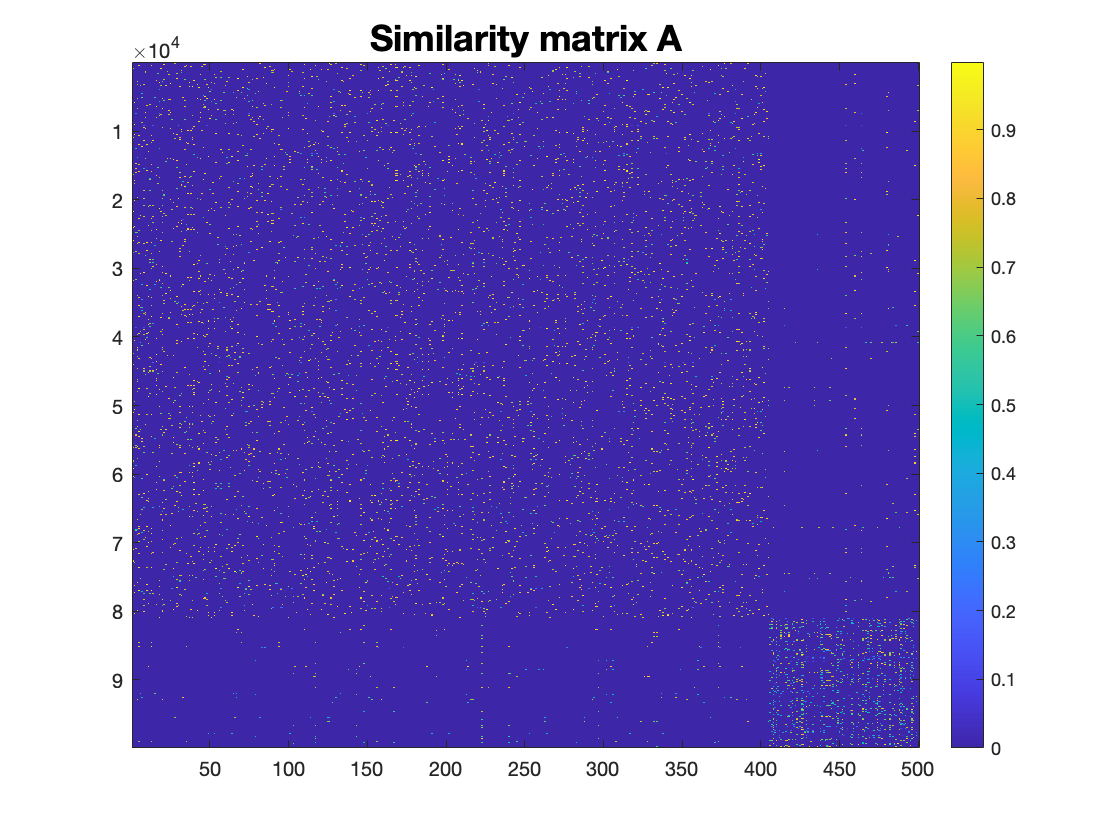

%%%%%%%%%%%%%%%%%%%% SIMILARITY MATRIX %%%%%%%%%%%%%%%%%%%%%%
r = 10;          %number of nearest landmark points 

[knnidx,knndists] = knnsearch(landmarks, Y, 'K', r+1, 'dist', 'seuclidean');
sigma = mean(knndists(:,end));
%%Cosine similarity method
% [knnidx,knndists] = knnsearch(landmarks, Y, 'K', r+1, 'dist', 'cosine');
% sigma = mean(knndists(:,end));
%O = ones(size(knndists));
%knndists=O-knndists;

A_knn = exp(-knndists(:,2:end).^2/(2*sigma^2));

A = zeros(n,m);
all_idx = (1:n)' + n * (knnidx(:,2:end)-1);
A(all_idx(:)) = A_knn(:);

A(1:n+1:(m-1)*n+m) = 0; % set diagonals to zero

figure; 
imagesc(A); 
colorbar
title('Similarity matrix A','fontsize',18)

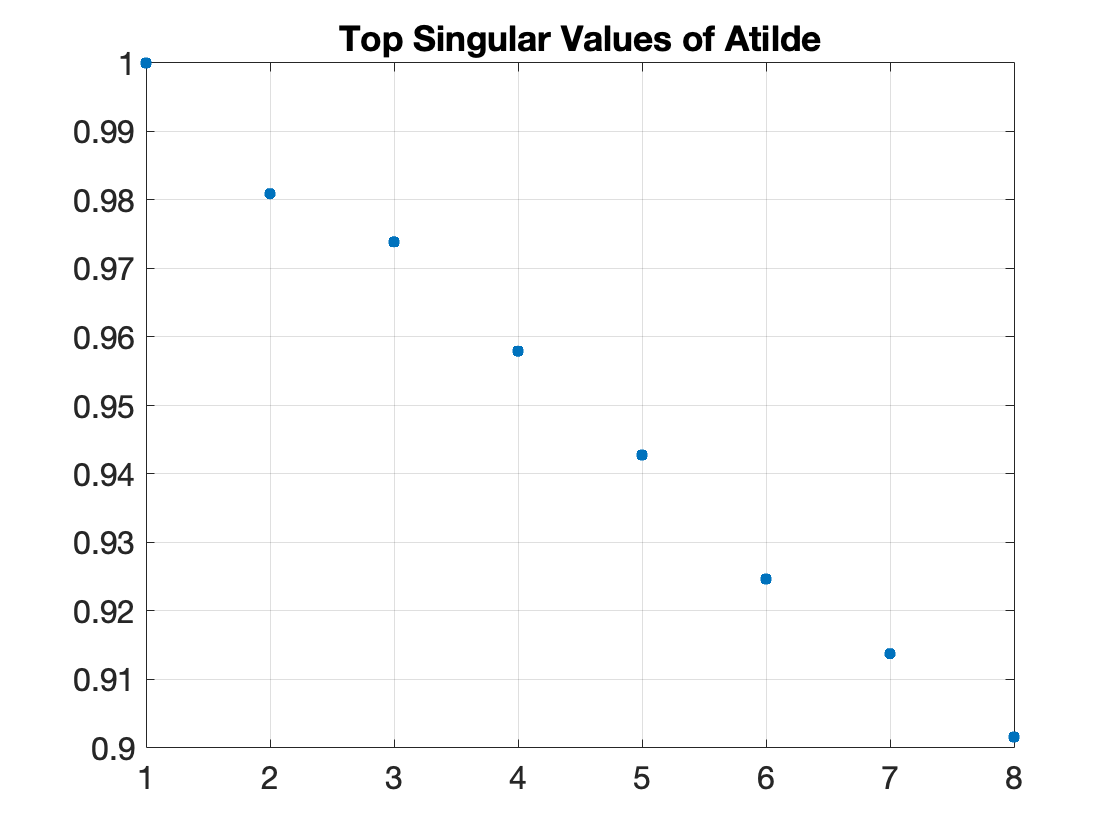

%%%%%%%%%%%%%%% PERFORM SPECTRAL CLUSTERING %%%%%%%%%%%%%%%%%%
D1 = sum(A,2); % row sums
D2 = sum(A,1); % column sums

Atilde  = A ./ sqrt(D1);
Atilde = Atilde ./ sqrt(D2);

k=4;

[U,S,V] = svds(Atilde, 2*k);

W = [U(:,2:k)./sqrt(D1);  V(:,2:k)./sqrt(D2')];
% if row sum is close to 0, remove that data point

figure; 
plot(diag(S), '.', 'markersize', 16, ...
    'MarkerEdgeColor', [0 0.447 0.741], ...
    'MarkerFaceColor', [0.301 0.745 0.933])
title('Top Singular Values of Atilde', 'fontsize',18)
set(gca,'fontsize',16)
grid on


labels_ncut = kmeans(W, 2, 'replicates', 10);

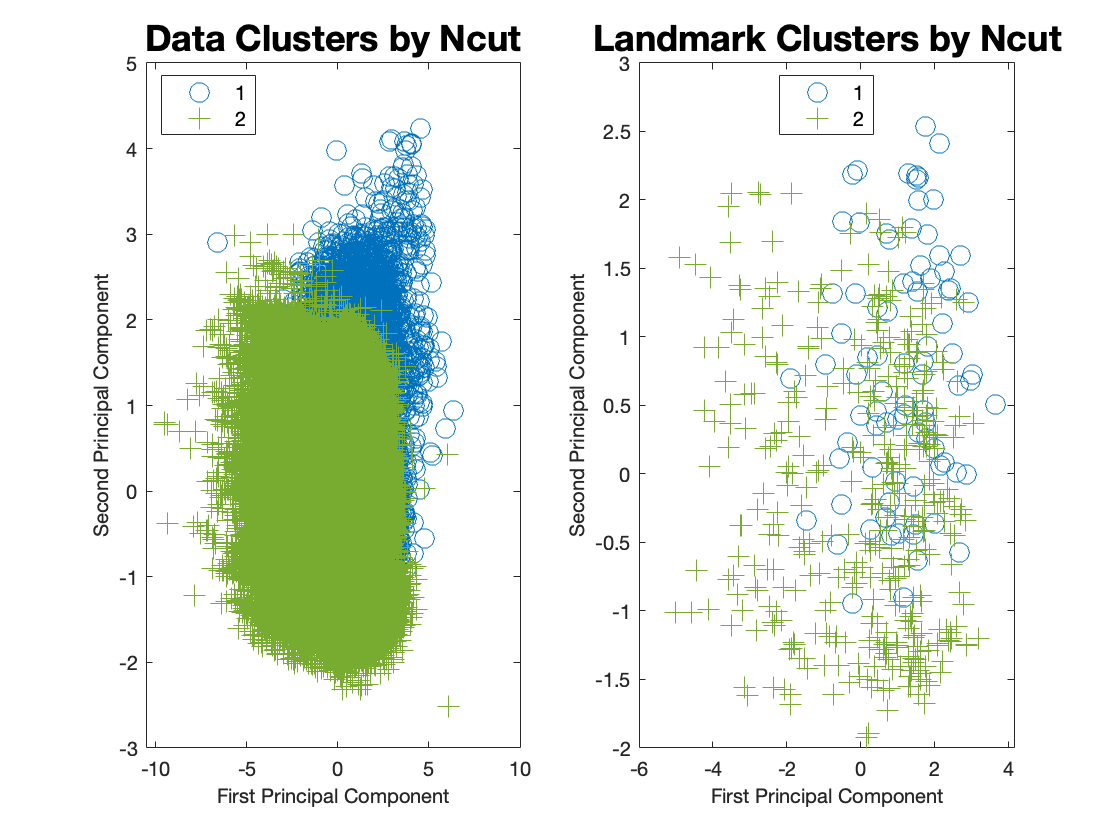

%%%%%%%%%%%%%%%%%%%%%%% PLOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure; 
subplot(1,2,1)
gscatter(Y(:,1), Y(:,2), labels_ncut(1:n), ...
    [0, .447, .741; .466, .674, .188], ...
    'o+', 10)
set(gca,'fontsize',10)
xlabel('First Principal Component', 'fontsize', 10)
ylabel('Second Principal Component', 'fontsize', 10)
legend('fontsize',10)
title('Data Clusters by Ncut','fontsize',18)

subplot(1,2,2)
gscatter(landmarks(:,1), landmarks(:,2), labels_ncut(n+1:end), ...
    [0, .447, .741; .466, .674, .188], ...
    'o+', 10)
set(gca,'fontsize',10)
xlabel('First Principal Component', 'fontsize', 10)
ylabel('Second Principal Component', 'fontsize', 10)
legend('fontsize',10)
title('Landmark Clusters by Ncut','fontsize',18)

truelabels1 = int64(truelabels);
labels_ncut

labels_ncut =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


err = clustering_error(labels_ncut, truelabels1)

err =    0.163261632616326


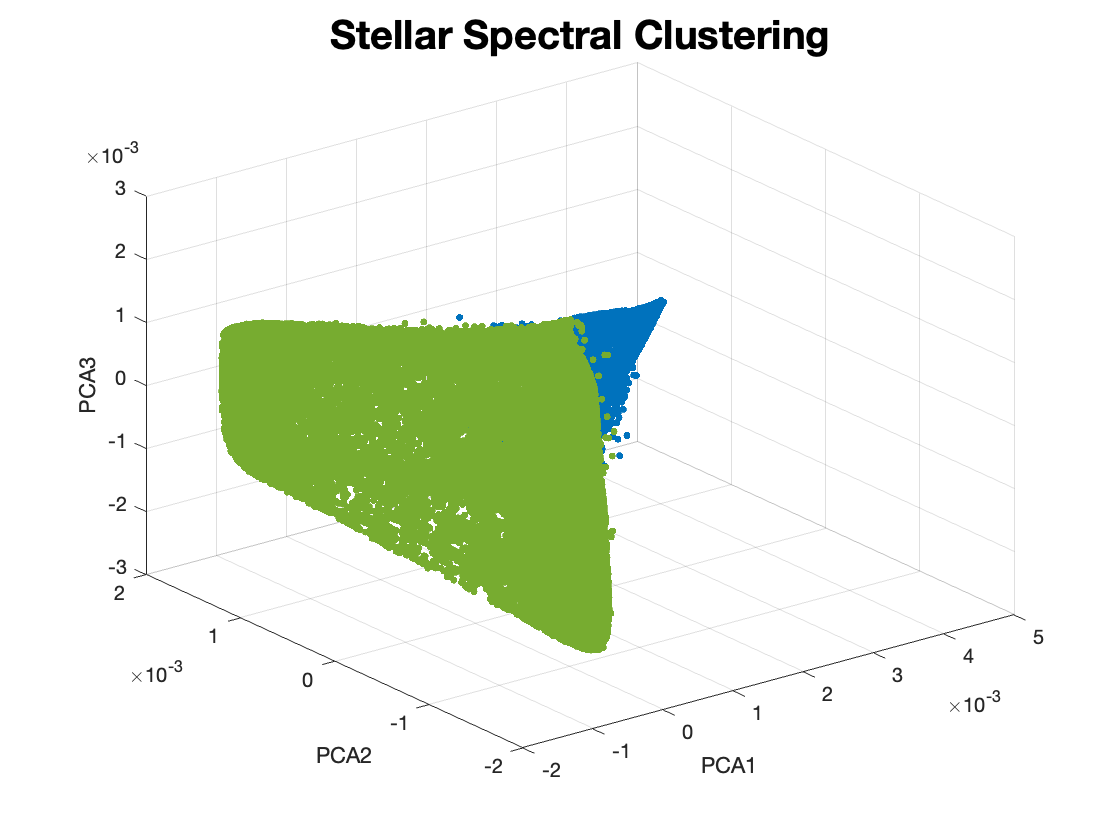


figure
plot3(W(labels_ncut==1,1),W(labels_ncut==1,2), W(labels_ncut==1,3),'.','MarkerSize',10, 'Color',[0; 0.447; 0.741]) 
hold on
plot3(W(labels_ncut==2,1),W(labels_ncut==2,2),W(labels_ncut==2,3),'.','MarkerSize',10, 'Color', [0.466; 0.674; 0.188])
title ('Stellar Spectral Clustering', 'FontSize', 20)
xlabel("PCA1")
ylabel("PCA2")
zlabel("PCA3")
grid on

hold off

function Y = pca(X) % PCA func

% compute Xtilde
Xtilde = X - mean(X);

% perform svd to Xtilde
s = svd(Xtilde);

% calculate explained scatter
scatter = cumsum(s.^2) / sum(Xtilde(:).^2);

% obatin dims needed or capture 95% scatter
dim95 = find(scatter > 0.95, 1);

% perform svd with trimmed dim
[U, S] = svds(Xtilde, dim95);

% get matrix y
Y = U.* diag(S)';
end